# **Redstone Control Performance**

**Hongseok Kim**

## I. Theoretical Review: PID Controller


$$\begin{array}{l}
1\ldotp \;\textrm{Angular}\;\textrm{Momentum}\;\textrm{Equation}\\
{\mathit{\mathbf{H}}}_{\textrm{SAT}} ={\mathit{\mathbf{H}}}_{\textrm{body}} +{\mathit{\mathbf{H}}}_{\textrm{RWA}} =J\omega_B +J\omega_{\textrm{RWA}} \\
\\
2\ldotp \;\textrm{Euler}\;\textrm{Equations}\;\textrm{of}\;\textrm{Rigid}\;\textrm{Body}\\
\frac{d{\mathit{\mathbf{H}}}_{\textrm{SAT}} }{\textrm{dt}}=J{\dot{\omega} }_B +I{\dot{\omega} }_{\textrm{RWA}} +\omega_B \times \left(J\omega_B +J\omega_{\textrm{RWA}} \right)=\tau_d \\
\textrm{let}\;\tau_d -\omega_B \times \left(J\omega_B +J\omega_{\textrm{RWA}} \right)=\tau_{\textrm{dw}} \;,\textrm{and}\;\textrm{assume}\;\tau_{\textrm{dw}} \left(t\right)\;\textrm{is}\;\textrm{step}\;\textrm{input}\\
\textrm{Disturbance}\;\textrm{term}\;\textrm{includes}\;\textrm{gyroscopic}\;\textrm{torque},\textrm{bearing}\;\textrm{friction}\\
\Rightarrow \tau_{\textrm{dw}} =J{\dot{\omega} }_B +I{\dot{\omega} }_{\textrm{RWA}} \\
\\
3\ldotp \;\textrm{Definition}\;\textrm{of}\;\textrm{Attitude}\;\textrm{Error}\\
\textrm{Reference}\;\textrm{input}:R_{\textrm{BI}}^* \;,\textrm{State}\;\textrm{input}:R_{\textrm{BI}} \Rightarrow \textrm{DCM}\;\textrm{based}\;\textrm{control}\\
\Rightarrow R_{\textrm{BI}}^* =R_E R_{\textrm{BI}} \;\iff R_E =R_{\textrm{BI}}^* R_{\textrm{BI}}^T \;\;\\
{\dot{R} }_{\textrm{BI}}^* =0={\dot{R} }_E R_{\textrm{BI}} +R_E {\dot{R} }_{\textrm{BI}} ={\dot{R} }_E R_{\textrm{BI}} +R_E \left\lbrack {-\omega }_B \times \right\rbrack \;R_{\textrm{BI}} \\
\Rightarrow {\dot{R} }_E R_{\textrm{BI}} =R_E \left\lbrack \omega_B \times \right\rbrack \;R_{\textrm{BI}} \;\therefore {\dot{R} }_E =R_E \left\lbrack \omega_B \times \right\rbrack \\
2\mathit{\mathbf{e}}=\left\lbrack \begin{array}{c}
R_E \left(2,3\right)-R_E \left(3,2\right)\\
R_E \left(3,1\right)-R_E \left(1,3\right)\\
R_E \left(1,2\right)-R_E \left(2,1\right)
\end{array}\right\rbrack ,\;\;\;2\dot{\mathit{\mathbf{e}}} =\left\lbrack \begin{array}{c}
{\dot{R} }_E \left(2,3\right)-{\dot{R} }_E \left(3,2\right)\\
{\dot{R} }_E \left(3,1\right)-{\dot{R} }_E \left(1,3\right)\\
{\dot{R} }_E \left(1,2\right)-{\dot{R} }_E \left(2,1\right)
\end{array}\right\rbrack \\
\dot{2\mathit{\mathbf{e}}} =\left\lbrack \begin{array}{c}
R_E \left(2,1\right)\;\omega_{\textrm{By}} -R_E \left(3,3\right)\;\omega_{\textrm{Bx}} -R_E \left(2,2\right)\;\omega_{\textrm{Bx}} +R_E \left(3,1\right)\;\omega_{\textrm{Bz}} \\
R_E \left(2,2\right)\;\omega_{\textrm{Bx}} -R_E \left(1,1\right)\;\omega_{\textrm{By}} -R_E \left(3,3\right)\;\omega_{\textrm{By}} +R_E \left(3,2\right)\;\omega_{\textrm{Bz}} \\
R_E \left(1,3\right)\;\omega_{\textrm{Bx}} -R_E \left(2,1\right)\;\omega_{\textrm{By}} -R_E \left(1,1\right)\;\omega_{\textrm{Bz}} -R_E \left(2,2\right)\;\omega_{\textrm{Bz}} 
\end{array}\right\rbrack \\
\;\;\;\;\approx \left\lbrack \begin{array}{c}
-R_E \left(3,3\right)\;\omega_{\textrm{Bx}} -R_E \left(2,2\right)\;\omega_{\textrm{Bx}} \\
-R_E \left(1,1\right)\;\omega_{\textrm{By}} -R_E \left(3,3\right)\;\omega_{\textrm{By}} \\
-R_E \left(1,1\right)\;\omega_{\textrm{Bz}} -R_E \left(2,2\right)\;\omega_{\textrm{Bz}} 
\end{array}\right\rbrack \approx -2\omega_B \;\\
\;\;\;\;\;\;\;\;\;\;\left(\textrm{We}\;\textrm{Assume}\;\textrm{non}-\textrm{diagonal}\;\textrm{terms}\;\textrm{of}\;R_E \;\textrm{are}\;\textrm{small}\right)
\end{array}$$



$$\begin{array}{l}
4\ldotp \textrm{Approximation}\;\textrm{and}\;\textrm{Connecting}\;\textrm{to}\;\textrm{Euler}\;\textrm{Angle}\\
\textrm{We}\;\textrm{can}\;\textrm{approximate}\;\mathit{\mathbf{e}}\;\textrm{as}\;\textrm{error}\;\textrm{euler}\;\textrm{angle}:\mathit{\mathbf{e}}\approx \left\lbrack \begin{array}{c}
\delta \phi \\
\delta \theta \\
\delta \phi 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\phi^* -\phi \\
\theta^* -\theta \\
\psi^* -\psi 
\end{array}\right\rbrack \\
\textrm{We}\;\textrm{are}\;\textrm{using}\;3-1-2\;\textrm{errer}\;\textrm{euler}\;\textrm{angles}\\
\dot{\mathit{\mathbf{e}}} \approx -\frac{1}{\cos \delta \phi }\left\lbrack \begin{array}{ccc}
\cos \delta \phi \cos \delta \theta  & 0 & \cos \delta \phi \sin \delta \theta \\
\sin \delta \phi \sin \delta \theta  & \cos \delta \phi  & -\cos \delta \theta \sin \delta \phi \\
-\sin \delta \theta  & 0 & \cos \delta \theta 
\end{array}\right\rbrack \omega_B \\
\textrm{We}\;\textrm{are}\;\textrm{assuming}\;\delta \phi ,\delta \theta ,\delta \psi \approx 0\\
\therefore \dot{\mathit{\mathbf{e}}} \approx \left\lbrack \begin{array}{c}
{\dot{\phi} }^* -\dot{\phi} \\
{\dot{\theta} }^* -\dot{\theta} \\
{\dot{\psi} }^* -\dot{\psi} 
\end{array}\right\rbrack \approx -\omega_B \Rightarrow \left\lbrack \begin{array}{c}
\dot{\phi} \\
\dot{\theta} \\
\dot{\psi} 
\end{array}\right\rbrack \approx \omega_B \\
\textrm{let}\;\left\lbrack \begin{array}{c}
\phi^* -\phi \\
\theta^* -\theta \\
\psi^* -\psi 
\end{array}\right\rbrack =\phi^* -\phi ,\textrm{then}\;\textrm{we}\;\textrm{can}\;\textrm{get}\;\textrm{following}\;\textrm{relationships}:\\
\mathit{\mathbf{e}}\approx \phi^* -\phi ,\;\;\dot{\mathit{\mathbf{e}}} \approx -\dot{\phi} \approx {-\omega }_B ,\;\ddot{\;\mathit{\mathbf{e}}} \approx -\ddot{\phi} \approx -{\dot{\omega} }_B ,\;\\
\int \mathit{\mathbf{e}}\;\textrm{dt}\approx \int \left(\phi^* -\phi \;\right)\textrm{dt}
\end{array}$$



$$\begin{array}{l}
5\ldotp \textrm{Derivation}\;\textrm{of}\;\textrm{Transfer}\;\textrm{Function}\\
\textrm{We}\;\textrm{can}\;\textrm{Model}\;\textrm{Reaction}\;\textrm{Wheel}\;\textrm{Torque}\;\textrm{by}\;\textrm{PID}\;\;\textrm{Control}\;\textrm{input}:\\
\tau_{\textrm{RWA}} =-I_{\textrm{RWA}} {\dot{\omega} }_{\textrm{RWA}} =K_P \;\mathit{\mathbf{e}}+K_I \int \mathit{\mathbf{e}}\;\textrm{dt}+K_d \dot{\mathit{\mathbf{e}}} \\
\;\;\;\;\;\;\;\;\;\;=K_P \;\left(\phi^* -\phi \right)+K_I \int \left(\phi^* -\phi \right)\;\textrm{dt}-K_d \dot{\phi} \\
\textrm{From}\;\textrm{angular}\;\textrm{momentum}\;\textrm{equation}:\\
\tau_{\textrm{dw}} =J{\dot{\omega} }_B +I{\dot{\omega} }_{\textrm{RWA}} =J\ddot{\phi} +K_P \;\left(\phi -\phi^* \right)+K_I \int \left(\phi -\phi^* \right)\;\textrm{dt}+K_d \dot{\phi} \;\\
\Rightarrow \textrm{Laplace}\;\textrm{Transform}\\
\tau_{\textrm{dw}} \left(s\right)={\textrm{Js}}^2 \phi \left(s\right)+K_P \left(\phi \left(s\right)-\phi^* \left(s\right)\right)+\frac{K_I }{s}\left(\phi \left(s\right)-\phi^* \left(s\right)\right)+K_D s\phi \left(s\right)\\
\left\lbrack {\textrm{Js}}^2 +K_p +\frac{K_I }{s}+K_D s\right\rbrack \phi \left(s\right)-\left\lbrack K_P +\frac{K_I }{s}\right\rbrack \phi^* \left(s\right)=\tau_{\textrm{dw}} \left(s\right)\\
\therefore \phi \left(s\right)=\frac{s\;\tau_{\textrm{dw}} \left(s\right)+\left(K_I +K_P s\right)\phi^* \left(s\right)}{{\textrm{Js}}^3 +K_D s+K_P s+K_I }\\
\textrm{We}\;\textrm{can}\;\textrm{assume}\;\tau_{\textrm{dw}} \left(s\right)\;\textrm{and}\;\phi^* \left(s\right)\;\textrm{are}\;\textrm{step}\;\textrm{input}:\;\\
\tau_{\textrm{dw}} \left(s\right)=\frac{\tau_{\textrm{dw}} }{s},\;\;\phi^* \left(s\right)=\frac{\phi^* }{s}\\
\textrm{Applying}\;\textrm{Final}\;\textrm{Value}\;\textrm{Theorem}:\\
\lim_{t\to \infty } \phi \left(t\right)=\lim_{s\to 0} s\phi \left(s\right)=\lim_{s\to 0} \frac{s\;\tau_{\textrm{dw}} +\left(K_I +K_P s\right)\phi^* }{{\textrm{Js}}^3 +K_D s+K_P s+K_I }=\phi^* \\
\textrm{We}\;\textrm{can}\;\textrm{conclude}\;\textrm{that}\;\textrm{in}\;\textrm{given}\;\textrm{system},\textrm{steady}-\textrm{state}\;\textrm{error}\;\textrm{is}\;0\ldotp \\
{\textrm{Let}}^{\prime } s\;\textrm{assume}\;\left|\tau_{\textrm{dw}} \right|\ll \left|\phi^* \right|\;\left(\textrm{Or}\;\textrm{we}\;\textrm{can}\;\textrm{quantify}\;\tau_{\textrm{dw}} =k\phi^* \right)\\
\textrm{then}\;\textrm{tranfer}\;\textrm{function}\;\textrm{is}\;\frac{\phi \left(s\right)}{\phi^* \left(s\right)}=\frac{K_P s+K_I }{{\textrm{Js}}^3 +K_D s+K_P s+K_I }\\
\textrm{And}\;\textrm{Closed}\;\textrm{loop}\;\textrm{characteristic}\;\textrm{equation}\;\textrm{is}\;{\textrm{Js}}^3 +K_D s+K_P s+K_I 
\end{array}$$


## II. Call the Parameters

addpath("Desktop/Redstone_Project/RS_LL/RS_LL_2_SAT_Attitude_Controller/")
SATParamsScript;


J = diag([200;100;150]);

K_P = 20;
K_I = 1;
K_D = 450;

Transfer_function_1 = tf([K_P,K_I],[J(2,2),K_D,K_P,K_I])

Transfer_function_1 =
 
            20 s + 1
  ----------------------------
  100 s^3 + 450 s^2 + 20 s + 1
 
Continuous-time transfer function.
Model Properties


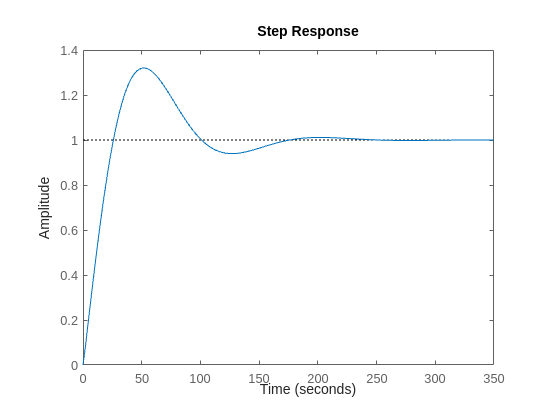

step(Transfer_function_1)

stepinfo(Transfer_function_1)

ans = struct with fields:
         RiseTime: 20.0024
    TransientTime: 160.2480
     SettlingTime: 160.2480
      SettlingMin: 0.9121
      SettlingMax: 1.3202
        Overshoot: 32.0199
       Undershoot: 0
             Peak: 1.3202
         PeakTime: 51.8794


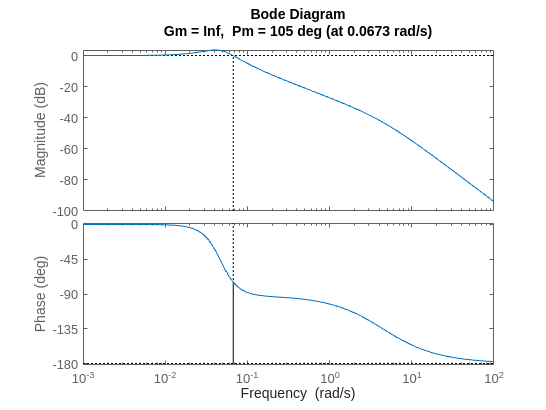

margin(Transfer_function_1)

allmargin(Transfer_function_1)

ans = struct with fields:
     GainMargin: Inf
    GMFrequency: Inf
    PhaseMargin: [-180 105.0889]
    PMFrequency: [0 0.0673]
    DelayMargin: [Inf 27.2429]
    DMFrequency: [0 0.0673]
         Stable: 1


bandwidth(Transfer_function_1)

ans = 0.0850

closed loop control bandwidth

## III. Theoretical Review: Motor Dynamics


$$\begin{array}{l}
\textrm{Motor}\;\textrm{Dynamics}\;\textrm{Equation}:\\
\frac{\omega \left(s\right)}{e_a \left(s\right)}=\frac{c_m }{\tau_m s+1}\\
c_m :\textrm{voltage}\;\left(V\right)\;\textrm{to}\;\textrm{Angular}\;\textrm{Rate}\;\left(\textrm{Rad}/s\right)\\
\tau_m :\textrm{Phase}\;\textrm{Lag}\;\textrm{time}\;\textrm{constant}\\
\textrm{Basic}\;\textrm{Equation}:\\
{\mathit{\mathbf{e}}}_a =\frac{1}{c_m }\left\lbrack -I_{\textrm{RWA}}^{-1} \tau_{\textrm{RWA}} \tau_m +\omega_{\textrm{RWA}} \right\rbrack \\
\\
\textrm{Environment}\;\textrm{Parameter}:\tau_m ,c_m ,I_{\textrm{RWA}} \\
\textrm{Input}\;\textrm{Parameter}:\tau_{\textrm{RWA}} ,\omega_{\textrm{RWA}} \\
\textrm{Output}\;\textrm{Parameter}:{\mathit{\mathbf{e}}}_a 
\end{array}$$


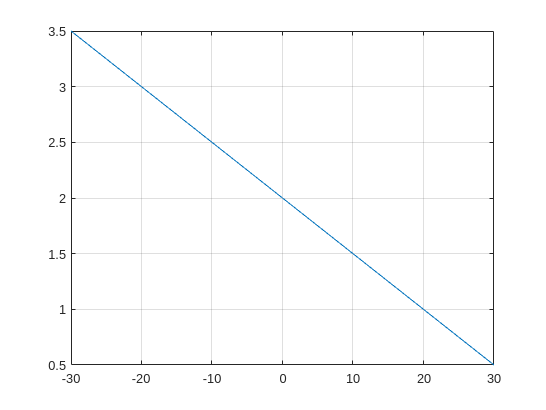

% 1 Axis Simulation
c_m = 1;
tau_m = 1/20;
I_RWA = 1;

omega_RWA = 2;
tau_RWA = linspace(-30,30);

e_a = 1/c_m * (-I_RWA^-1 * tau_m * tau_RWA + omega_RWA);
plot(tau_RWA,e_a)
grid on